**ΤΕΧΝΟΛΟΓΙΑ ΉΧΟΥ **

**Εργασία 1**

**Παναγιώτα Μωραΐτη** 

1. Επεξεργασία Ήχου Βραχέως Χρόνου

[x, fs] = audioread('guit2.wav');
frame = 256;
ovrlp = 0.5;
soundsc(x, fs); % Initial sound

Παρακάτω με την frame_wind διαιρούμε μια κυματομορφή ήχου σε μικρότερα τμήματα με επικάλυψη και με την frame_recon τα ενώνουμε μεταξύ τους. Οπότε με την ανακατασκευή δεν αλλοιώνεται η κυματομορφή εισόδου.

X = frame_wind (x, frame, ovrlp);
y = frame_recon (X, ovrlp);
soundsc(y, fs); % Final sound

Όταν ακούμε τον αρχικό ήχο x και τον ήχο y, παρατηρούμε ότι η ανακατασκευή με αυτήν την τεχνική είναι τέλεια.

2. Χωρισμός Φωνούμενου/Μη-φωνούμενου Τμήματος

% a)
[x, fs] = audioread('guit1.wav');
frame = 256;
ovrlp = 0.5;
soundsc(x, fs); % Initial sound
x = frame_wind (x, frame, ovrlp);
XF = fft(x);
Elow = sum(abs(XF(1:frame/4,:)).^2);
Ehigh = sum(abs(XF(frame/4+1:frame/2,:)).^2);

% b)
a = 1;
voiced_unvoiced = Ehigh./Elow < a;
% voiced = 1
% unvoiced = 0

% c)
x1 = x;
x2 = x;
for k = 1:length(voiced_unvoiced)
    if voiced_unvoiced(k) == 0
        x1(:, k) = 0;
    else
        x2(:, k) = 0;
    end
end

y1 = frame_recon (x1, ovrlp);
y2 = frame_recon (x2, ovrlp);
y = y1+y2;

soundsc(y1, fs); % Sound with voiced

soundsc(y2, fs); % Sound with unvoiced

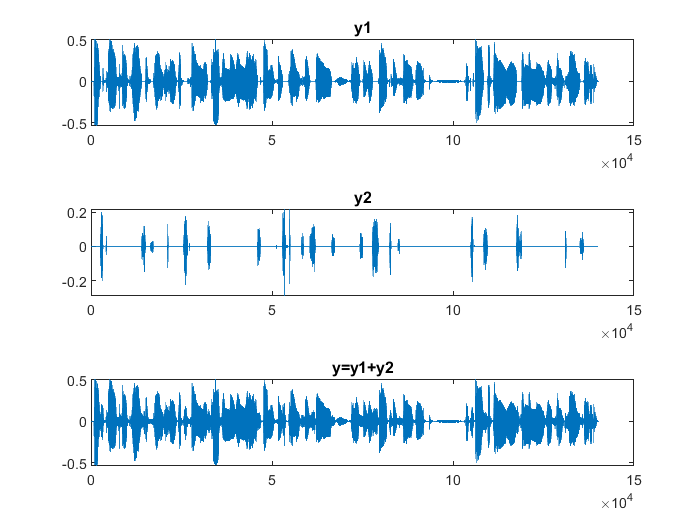

soundsc(y, fs); % Final sound

tiledlayout(3, 1)
nexttile
plot(y1);
title('y1');
nexttile
plot(y2);
title('y2');
nexttile
plot(y);
title('y=y1+y2');

Σε αυτήν την τεχνική, χρησιμοποιούμε το μετασχηματισμό fourier για να μεταφερθούμε από το πεδίο του χρόνου, στο πεδίο της συχνότητας.

Η y1 περιέχει όλους του φθόγγους που έχουν υψηλή ενέργεια (έμφωνοι φθόγγοι), οι οποίοι αποτελούν σήματα χαμηλής συχνότητας και η y2, αυτούς με τη χαμηλότερη ενέργεια (άφωνοι φθόγγοι), οι οποίοι αποτελούν σήματα υψηλής συχνότητας (υψίσυχνα). Γι' αυτό το λόγο όταν ακούμε τον ήχο y1, ο ομιλητής γίνεται ψευδός, ενώ όταν στον y2 το μόνο που ακούγεται είναι τα σίγμα με κάποιες παύσεις (τστστσ).

Το άθροισμα των δύο γραφικών παραστάσεων μας δίνει τον αρχικό ήχο, με κάποιες πολύ μικρές όμως αλλοιώσεις λόγω της επεξεργασίας που έγινε.

Παρακάτω εφαρμόσαμε την τεχνική και σε μια δική μας ηχογράφηση.

% d)
% recorder = audiorecorder(fs, 8, 1);
% disp('Start speaking.');
% recordblocking(recorder, 5);
% disp('End of Recording.');
% play(recorder);
% filename = 'my_recording.wav';
% y = getaudiodata(recorder);
% audiowrite(filename, y, fs)

[x, fs] = audioread('recording.wav');
frame = 256;
ovrlp = 0.5;
frequency = 16000;
soundsc(x, fs); % Initial sound

x = frame_wind (x, frame, ovrlp);
XF = fft(x);
Elow = sum(abs(XF(1:frame/4,:)).^2);
Ehigh = sum(abs(XF(frame/4+1:frame/2,:)).^2);

a = 0.5;
voiced_unvoiced = Ehigh./Elow < a;

x1 = x;
x2 = x;
for k = 1:length(voiced_unvoiced)
    if voiced_unvoiced(k) == 0
        x1(:, k) = 0;
    else
        x2(:, k) = 0;
    end
end

y1 = frame_recon (x1, ovrlp);
y2 = frame_recon (x2, ovrlp);
y = y1+y2;

soundsc(y1, fs); % Sound with voiced

soundsc(y2, fs); % Sound with unvoiced

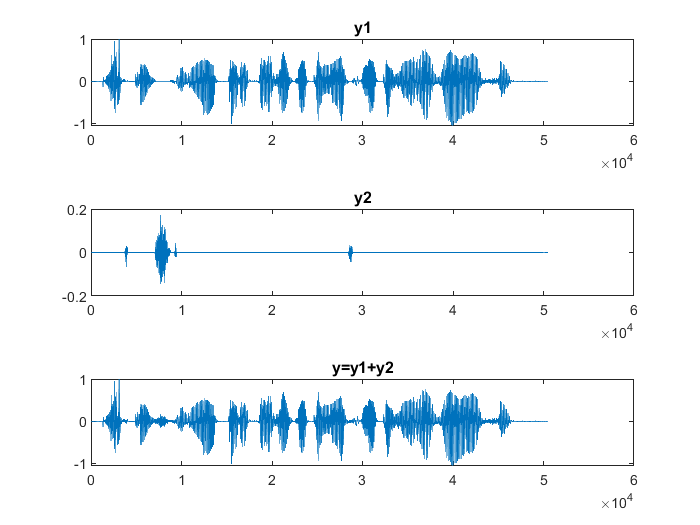

soundsc(y, fs); % Final sound

tiledlayout(3, 1)
nexttile
plot(y1);
title('y1');
nexttile
plot(y2);
title('y2');
nexttile
plot(y);
title('y=y1+y2');

Αφού, δοκιμάσαμε διάφορες τιμές για το a, παρατηρήσαμε ότι όσο μεγαλώνει τόσο καλύτερα μπορούμε να ακούσουμε τους φθόγγους με τις χαμηλότερες ενέργειες (πχ. σίγμα). Όσο το a γίνεται πιο μικρό, κόβονται οι φθόγγοι με την πιο χαμηλή ενέργεια και ο ομιλητής γίνεται όλο και πιο ψευδός. Αν επίλεξουμε τη σωστή τιμή για το threshold, με αυτήν την τεχνική ανάλογα με τον ομιλητή που έχουμε, μπορούμε να κάνουμε το σίγμα και άλλους φθόγγους με χαμηλή ενέργεια να ακούγονται λιγότερο (πχ. σε μια θεατρική παράσταση ώστε να βελτιωθεί η ποιότητα του ήχου που ακούνε οι θεατές). 

Ένα παράδειγμα ανακατασκευής ήχου για να μην ακούγετει τόσο το σίγμα είναι: y = y1+0.3*y2.

3. Εξαγωγή Ρυθμικού Σολφέζ από μουσικό κομμάτι

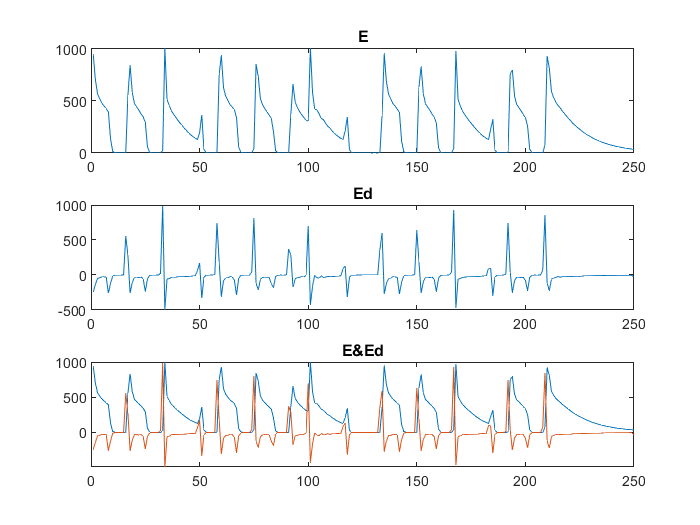

% a)
[x, fs] = audioread('smoke.wav');
frame = 1024;
ovrlp = 0.5;
soundsc(x, fs); % Initial sound

X = frame_wind (x, frame, ovrlp);
XF = fft(X);
Elow = sum(abs(XF(1:frame/4,:)).^2);
Ehigh = sum(abs(XF(frame/4+1:frame/2,:)).^2);

E = Ehigh + Elow;

% b)
Ed = diff(E);

subplot(3,1,1);
plot(E);
title('E');
xlim([0, 250]);
subplot(3,1,2);
plot(Ed);
title('Ed');
subplot(3,1,3);
plot(E);
hold on
plot(Ed);
title('E&Ed');
xlim([0, 250]);

Από την κυματομορφή της ενέργειας θέλουμε να πάρουμε τα σημεία στα οποία έχουμε αρχή νότας, δηλαδή τα σημεία στα οποία η ενέργεια από πολύ μικρή αυξάνεται απότομα. Παρατηρώντας την παράγωγο την ενέργειας, διαπιστώνουμε ότι όπου κορυφώνεται η παράγωγος (τοπικό μέγιστο), εκεί αρχίζει κάποια νότα, με βάση το διάγραμμα που απεικονίζει την Ε. Οπότε, μετά από πολλές δοκιμές δώσαμε κάποια τιμή σαν threshold και όταν η παράγωγος είχε μεγαλύτερο πλάτος από αυτή την τιμή, τότε παίρναμε το σημείο σαν αρχή νότας. 

Επίσης, παρατηρήσαμε ότι στην αρχή του τραγουδιού, ενώ έχουμε αρχή νότας, αυτό δε φαίνεται από την παράγωγο, με βάση το παραπάνω κριτήριο που ορίσαμε, οπότε τη συμπεριλάβαμε χειροκίνητα.

% c)
Y = zeros(size(X));

for k = 1:length(Ed)
    if k == 1
        Y(:, k) = 1;
        % k
        % Ed(k)        
    end
    if Ed(k) > 320
        Y(:, k) = 1;
        % k
        % Ed(k)
    end
end

% d)
y = frame_recon (Y, ovrlp);
soundsc(y, fs); % Solfez

Ο πίνακας y περιέχει άσσους στα σημεία στα οποία αρχίζει μια νότα, με βάση το κριτήριο που αναφέραμε παραπάνω και σε όλες τις υπόλοιπες θέσεις περιέχει μηδενικά.

Οπότε, από την κυματομορφή y, παρατηρούμε ότι ακούμε ένα ρυθμικό ήχο σαν χτύπημα που αναπαράγει όσο καλύτερα μπορεί τον ρυθμό του τραγουδιού. Στην ουσία, αυτό που ακούμε είναι το ρυθμικό σολφέζ του τραγουδιού.

Επίσης, καταλαβαίνουμε καλύτερα ότι έχουμε αναπαράγει το σωστό ρυθμό, όταν ταυτόχρονα με το σολφέζ παίζει και το τραγούδι.

[x, fs] = audioread('smoke.wav');
soundsc(x, fs); % Initial sound

y = frame_recon (Y, ovrlp);
soundsc(y, fs); % Solfez

4. Αυτόματος Ανιχνευτής Ομιλίας (Voice Activity Detector–VAD)

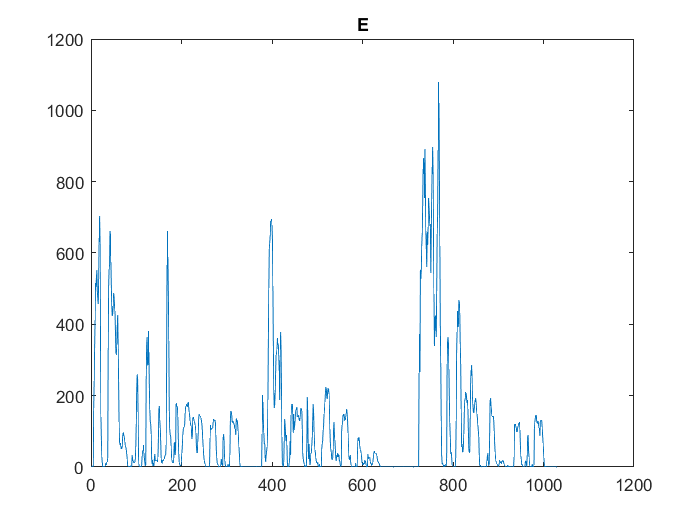

% a)
[x, fs] = audioread('guit2.wav');
frame = 256;
ovrlp = 0.5;
soundsc(x, fs); % Initial sound

X = frame_wind (x, frame, ovrlp);
XF = fft(X);
Elow = sum(abs(XF(1:frame/4,:)).^2);
Ehigh = sum(abs(XF(frame/4+1:frame/2,:)).^2);

E = Ehigh + Elow;

% b)
figure
plot(E);
title('E');

Από την παράπανω κυματομορφή, μπορούμε να ορίσουμε ένα threshold και αν η ενέργεια είναι μικρότερη από αυτό, τότε δε συμπεριλαμβάνουμε τον ήχο στην ανακατασκευή. Όσο μικρότερο είναι το threshold, τόσο καλύτερη είναι η ποιότητα του ήχου, γίνεται όμως λιγότερη εξοικονόμηση στην μπαταρία του τηλεφώνου, αν υποθέσουμε ότι ο κώδικας μας χρησιμοποιείται σε κάποια πραγματική εφαρμογή.

Κατά βάση, θέλουμε η ποιότητα του ήχου να είναι όσο το δυνατόν καλύτερη (ανακατασκευασμένος ήχος όσο πιο κοντά γίνεται στον αρχικό). Έπειτα, μας ενδιαφέρει να εξοικονομήσουμε όσο περισσότερη μπαταρία γίνεται, οπότε πρέπει να ορίσουμε το threshold, με βάση αυτά τα δύο κριτήρια.

Οπότε, εμείς πήραμε το threshold σαν κάποια πολύ μικρή τιμή ενέργειας, ώστε να μην αλλοιώνεται ο ήχος. Παρ' όλα αυτά το ποσοστό μπαταρίας που εξοικονομούμε είναι ικανοποιητικό.

% c)
Y = X;

for k = 1:length(E)
    if E(k) < 10
        Y(:, k) = 0;
    end
end


% d)
y = frame_recon (Y, ovrlp);
soundsc(y, fs); % Final sound

Παρατηρούμε ότι οι παύσεις, δηλαδή εκεί που δεν παρατηρείται ομιλία από τον χρήστη, δεν συμπεριλαμβάνονται στον ανακατασκευασμένο ήχο (το μικρόφωνο κλείνει). Η ποιότητα όμως του ήχου, σε σχέση με την αρχική είναι σχεδόν ίδια.

Αν το threshold αυξηθεί, τότε χάνουμε τους φθόγγους με την χαμηλότερη ενέργεια και υπάρχει σημαντική αλλοίωση του ήχου.

% e)
num_of_frames_inactive = 0;

for k = 1:length(Y)
    if Y(:, k) == 0
        num_of_frames_inactive = num_of_frames_inactive + 1;
    end
end

all_frames = length(Y);
num_of_frames_active = all_frames-num_of_frames_inactive;
percentage_of_inactive = (num_of_frames_inactive*100)/all_frames;

fprintf('All the frames are: %d\n', all_frames);

All the frames are: 1029


fprintf('Number of frames inactive is: %d\n', num_of_frames_inactive);

Number of frames inactive is: 369


fprintf('Number of frames active is: %d\n', num_of_frames_active);

Number of frames active is: 660


fprintf('\n');
fprintf('Percentage of frames inactive is: %0.2f%%\n', percentage_of_inactive);

Percentage of frames inactive is: 35.86%


Οπότε, το κινητό τηλέφωνο εξοικονομεί 35.86% της ενέργειας σε σχέση με πριν.